clear
close all

m = linspace(-10,20,50);
d = linspace(-70,70,50);

[D,~] = meshgrid(d);
[~,M] = meshgrid(m);

%presets
len =length(m);
error = zeros(len);

% model
x = linspace(0,10,5)';
y = 5.*x + 5;


for i=1:len
    for j=1:len
        error(i,j) = sum((y-(M(i,j).*x + D(i,j))).^2);
    end
end


minima=find(error==min(error,[],'all'))

minima = 1375

[dx,dy]=gradient(error,1);

%pick random point of cost function
index = randi(len^2)

index = 891


eM = M(index)

eM = 14.4898

De = D(index)

De = -21.4286

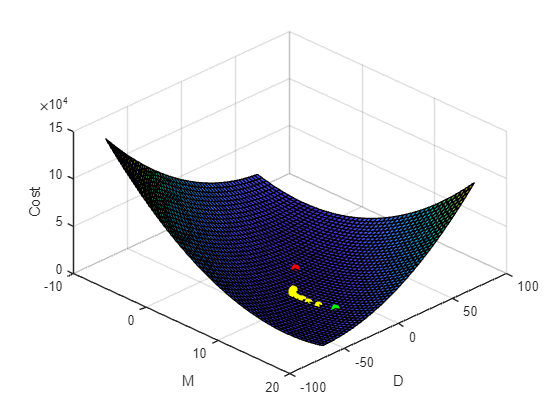


surf(M,D,error)
hold on
scatter3(M(minima),D(minima),error(minima),'filled','MarkerFaceColor','r')      %plot minima of cost function matrix error
scatter3(M(index),D(index),sum((y-(M(index).*x + D(index))).^2),'filled','MarkerFaceColor','g') %plot starting point

xlabel('M')
ylabel('D')
zlabel('Cost')
view(45,45)
lern_rate = 0.001;

for t = 1:100
    %compute partial derivatives for each parameter to be optimized
    dm = sum(2*x.*(eM.*x + De - y));
    dd = sum(2*(eM.*x - y + De));

    %move parameters closer to minima by using the gradient
    %without momentum
    eM = eM - (dm * lern_rate);
    De = De - (dd * lern_rate);

    %plot loaction after each descent
    scatter3(eM,De,sum((y-(eM.*x + De)).^2),'filled','MarkerFaceColor','y')
    %pause(10e-10)
end


eM

eM = 7.6368

De

De = -14.6031


%
% while dd~=0 && dm~=0
%
%
%     dd = sum(2*(D(indeU) - M(indeU).*x + y));
%
% 
%     if dd>0
%         indeU=indeU-1*len;
%     elseif dd==0
%     else
%         indeU=indeU+1*len;
%     end
%     scatter3(M(indeU),D(indeU),error(indeU),'filled','MarkerFaceColor','y')
% 
%    dm = sum(2*x.*(M(indeU).*x - D(indeU) - y));
% 
%     if dm>0
%         indeU=indeU-1;
%     elseif dm==0
%     else
%         indeU=indeU+1;
%     end
% 
%     pause(10e-5)
%     scatter3(M(indeU),D(indeU),error(indeU),'filled','MarkerFaceColor','y')
%     
%    
% end
% M(indeU)
% D(indeU)